% this script is for reading the config_A set of reference wire scans
% note that additional plots are commented out with a " %%% " remove to view

clear all;
close all;

filepath = 'C:\Users\985080\OneDrive - Swansea University\Desktop\'

filepath = 'C:\Users\985080\OneDrive - Swansea University\Desktop\'

%filepath = 'C:\Users\Mog\Desktop\'; %this is an example filepath - please change as needed!

filename1 = 'Config_A_wire_reference_measurement_part_1';
filename2 = 'Config_A_wire_reference_measurement_part_2';
filename3 = 'Config_A_wire_reference_measurement_part_3';

a_path = strcat(filepath, filename1);
b_path = strcat(filepath, filename2);
c_path = strcat(filepath, filename3);


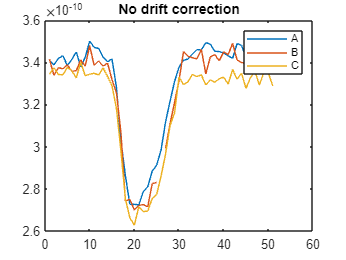

a = load(a_path); b = load(b_path); c = load(c_path);
A = a.pressure; B = fliplr(b.pressure); C = c.pressure;
plot(A); hold on; plot(B); plot(C); hold off; legend('A', 'B', 'C'); title('No drift correction')

A_index_1 = 15; A_index_2 = 31; B_index_1 = 14; B_index_2 = 31; C_index_1 = 13; C_index_2 = 30;
x_full = 1:length(A);

% DRIFT CORRECT A
%splitting the data up
A_1 = A( 1:A_index_1 ); A_2 = A( (A_index_1+1): A_index_2); A_3 = A( (A_index_2+1):end);

%defining the splitting indexes
x_A1 = 1:A_index_1; x_A2 = (A_index_1+1):A_index_2; x_A3 = (A_index_2+1):length(A);

%selects the data applicable to drift correction
A_selected = [A_1, A_3]; x_A_selected = [x_A1, x_A3];

%%% plot(A_selected); title('Selected LHS and RHS for drift correction');

%generates the fitting parameters
[a b]=polyfit(x_A_selected, A_selected, 1);

%generates the full fitting for all indexes using above fitting parameters
fitmag=a(2)+a(1)*x_full;

A_corrected=(A./(fitmag));
%%% plot(A_corrected); title('Drift Corrected Data');

% DRIFT CORRECT B
%splitting the data up
B_1 = B( 1:B_index_1 ); B_2 = B( (B_index_1+1): B_index_2); B_3 = B( (B_index_2+1):end);

%defining the splitting indexes
x_B1 = 1:B_index_1; x_B2 = (B_index_1+1):B_index_2; x_B3 = (B_index_2+1):length(B);

%selects the data applicable to drift correction
B_selected = [B_1, B_3]; x_B_selected = [x_B1, x_B3];

%%% plot(B_selected); title('Selected LHS and RHS for drift correction');

%generates the fitting parameters
[a b]=polyfit(x_B_selected, B_selected, 1);

%generates the full fitting for all indexes using above fitting parameters
fitmag=a(2)+a(1)*x_full;

B_corrected=(B./(fitmag));
%%% plot(B_corrected); title('Drift Corrected Data');

% DRIFT CORRECT C
%splitting the data up
C_1 = C( 1:C_index_1 ); C_2 = C( (C_index_1+1): C_index_2); C_3 = C( (C_index_2+1):end);

%defining the splitting indexes
x_C1 = 1:C_index_1; x_C2 = (C_index_1+1):C_index_2; x_C3 = (C_index_2+1):length(C);

%selects the data applicable to drift correction
C_selected = [C_1, C_3]; x_C_selected = [x_C1, x_C3];

%%% plot(B_selected); title('Selected LHS and RHS for drift correction');

%generates the fitting parameters
[a b]=polyfit(x_C_selected, C_selected, 1);

%generates the full fitting for all indexes using above fitting parameters
fitmag=a(2)+a(1)*x_full;

C_corrected=(C./(fitmag));
%%% plot(C_corrected); title('Drift Corrected Data');


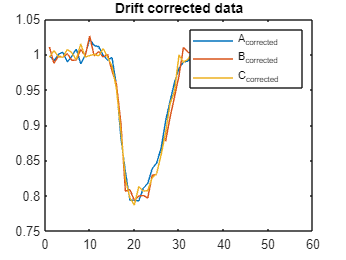

%plotting all drift corrected data
plot(A_corrected); hold on; plot(B_corrected); plot(C_corrected); legend('A_{corrected}', 'B_{corrected}', 'C_{corrected}'); hold off;
title('Drift corrected data')

%Combined datasets
full_corrected = [ A_corrected' , B_corrected' , C_corrected' ];
mean_corrected = mean(full_corrected, 2, 'omitnan');
%%% plot(mean_corrected);

%x-axis discretisation
wire_scan_width = (100/25) * 0.635;
wire_scan_positions = linspace( -wire_scan_width/2 , wire_scan_width/2, length(mean_corrected) );

%flips and normalises the data
full_corrected = -full_corrected + 1;
full_norm = full_corrected ./ max(full_corrected);
%%% plot(full_norm); title('normalised and flipped drift corrected data');

%fliplr dataset (since negative gyromagnetic ratio)
full_norm = flipud(full_norm);

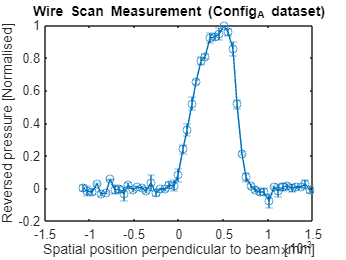

missing_data_index = 26; %error from manual
offset = 0.2;

%Calculates the mean and standard deviation of the datasets
mean_corrected = mean(full_norm, 2, 'omitnan');
%%% plot(wire_scan_positions, mean_corrected, 'o-');
stdev_corrected = std(full_norm', 'omitnan');

%splits stdev into 3 sections
std1 = stdev_corrected(1:(missing_data_index-1));
std2 = stdev_corrected(missing_data_index);
std3 = stdev_corrected((missing_data_index+1):end);

error1 = std1 / sqrt(3); error2 = std2 / sqrt(2); error3 = std3 / sqrt(3);
error_full = [ error1, error2, error3 ];

errorbar((wire_scan_positions + offset)*1e-3, mean_corrected, error_full, 'o-');
title('Wire Scan Measurement (Config_A dataset)');
xlabel('Spatial position perpendicular to beam [mm]');
ylabel('Reversed pressure [Normalised]');